**RMSE COMPARISON**

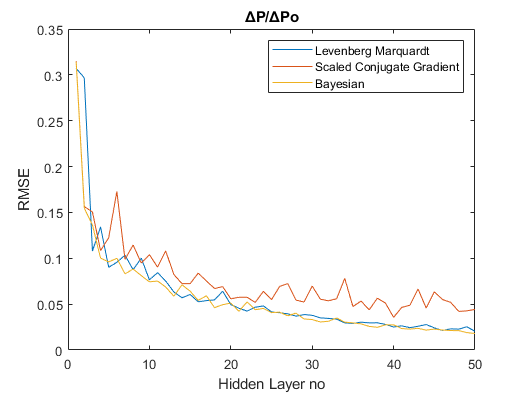

a=figure();
set(gca,'Box','on')
hold on;
plot(1:50,rms_train_lm(:,1));
plot(1:50,rms_train_scg(:,1));
plot(1:50,rms_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(rmse).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

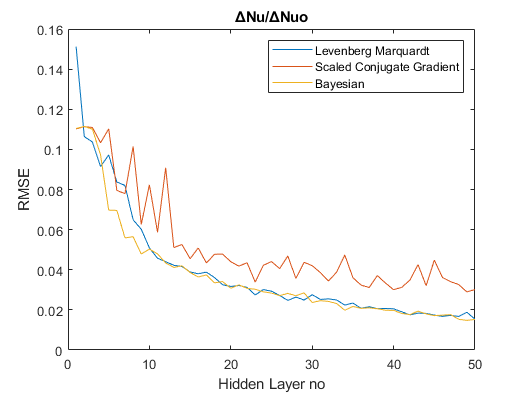


b=figure();
set(gca,'Box','on')
hold on;
plot(1:50,rms_train_lm(:,2));
plot(1:50,rms_train_scg(:,2));
plot(1:50,rms_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('RMSE')
title('Nu/Nuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(rmse).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**R2 COMPARISON**

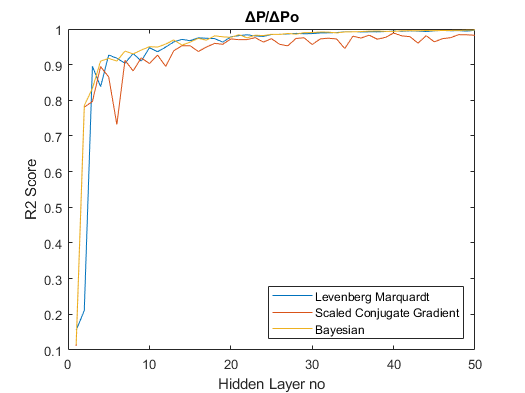

c=figure();
set(gca,'Box','on')
hold on;
plot(1:50,r2_train_lm(:,1));
plot(1:50,r2_train_scg(:,1));
plot(1:50,r2_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('R2 Score')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(r2).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

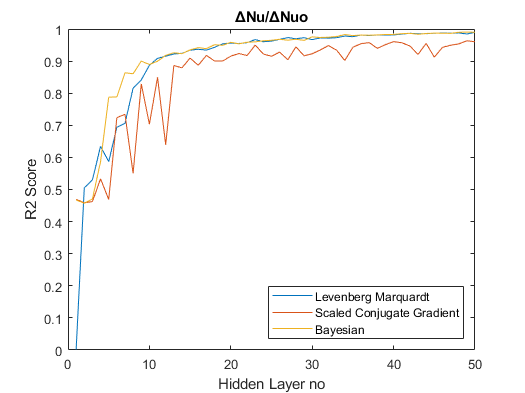


d=figure();
set(gca,'Box','on')
hold on;
plot(1:50,r2_train_lm(:,2));
plot(1:50,r2_train_scg(:,2));
plot(1:50,r2_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('R2 Score')
title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(r2).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**MAPE COMPARISON**

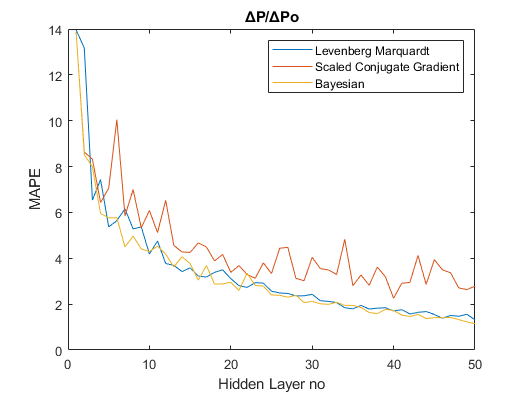

e=figure();
set(gca,'Box','on')
hold on;
plot(1:50,mape_train_lm(:,1));
plot(1:50,mape_train_scg(:,1));
plot(1:50,mape_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('MAPE')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(mape).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

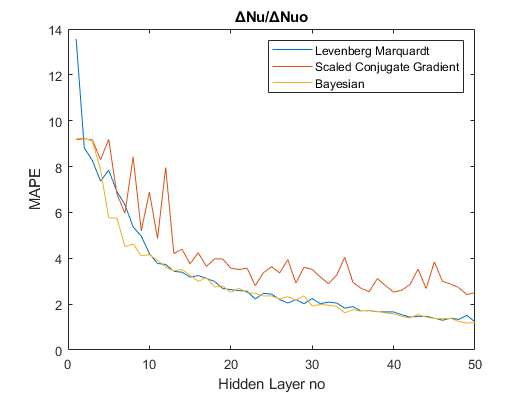


f=figure();
set(gca,'Box','on')
hold on;
plot(1:50,mape_train_lm(:,2));
plot(1:50,mape_train_scg(:,2));
plot(1:50,mape_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('MAPE')
title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(mape).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**Comparison Between Ann and Corelation**

Unrecognized function or variable 'yActual'.

for i=1:2
    figure()
    plot(yValTrue_lm(i,:),yVal_lm(i,:),'x','color','#D95319');hold on;
    plot(0:5,0:5,'color','k');
    if i==1
        plot(yActual,yPredict_dt_p,'o','color','b')
    else
        plot(data_lr.delNudelNuo,yPredict_dt_nu,'o','color','b')
    end
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Validation Data','','Co-relation data','location','northwest')
    ylabel('Predicted Value(Lavenberg Marquardt)')
    xlabel('Actual Value')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/Comparison/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_LM_1)
    else
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/Comparison/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_LM_1)
    end
end

table_2=[T_lm_val;T_scg_val;T_bay_val]

table_2 = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.015216    0.00048102    0.021932    0.99635    1.3334
    {'Nusselt ratio' }    0.012437    0.00036894    0.019208    0.98389    1.4704
    {'Pressure_ratio'}    0.036617     0.0026434    0.051414    0.97995    3.1823
    {'Nusselt ratio' }    0.026201     0.0013526    0.036777    0.94094    3.0984
    {'Pressure_ratio'}    0.013601    0.00038339     0.01958    0.99709    1.2247
    {'Nusselt ratio' }    0.011275    0.00030884    0.017574    0.98651    1.3346


writetable(table_2,'D:/Matlab Drive/Research/Table/Performence ( (All Algorithm) validation set.xlsx')
table_1=[T_lm_train;T_scg_train;T_bay_train]

table_1 = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.015251    0.00047388    0.021769    0.99575    1.3288
    {'Nusselt ratio' }    0.011725    0.00030094    0.017348    0.98685    1.3744
    {'Pressure_ratio'}    0.038304     0.0029964     0.05474    0.97314    3.3152
    {'Nusselt ratio' }    0.026266     0.0013793    0.037139    0.93973    3.0742
    {'Pressure_ratio'}    0.013591    0.00037481     0.01936    0.99664    1.2109
    {'Nusselt ratio' }    0.010811    0.00024907    0.015782    0.98912    1.2673


writetable(table_1,'D:/Matlab Drive/Research/Table/Performence (All Algorithm) Training set.xlsx')

% sample=datasample(1:3276,300);
% sample_set=[yVal_lm' yValTrue_lm']';
% sample_set_lm=sample_set(:,sample)
% 
% x_sample=x';
% x_sample=x_sample(:,tr_lm.valInd);
% x_sample=x_sample(:,sample)
% 
% yPredict_dt_sample_p=predict(treeModel_p,x_sample')
% yPredict_dt_sample_nu=predict(treeModel_nu,x_sample')

testing_data_p;
testing_data_nu;
x(tr_lm.valInd,:);
Real_value=yValTrue_lm';
Predicted_value=yVal_bay';
yPredict_lr_sample_p=predict(linearModel_p,data_lr(tr_lm.valInd,:));
yPredict_lr_sample_nu=predict(linearModel_nu,data_lr(tr_lm.valInd,:));

sample=datasample(1:2730,150);

T=[testing_data_p(:,1:5),Real_value,Predicted_value,anfisoutput_p{3},anfisoutput_nu{3},yPredict_lr_sample_p,yPredict_lr_sample_nu]

T =    50.0000         0    1.5850    0.2000    0.2000    1.8266    1.0006    1.8171    1.0211    1.7653    1.0057    1.8823    0.8936
   50.0000         0    2.5750    0.2000    0.2000    1.8557    0.9992    1.8365    1.0156    1.7903    1.0053    1.8896    0.8989
   50.0000         0    3.0700    0.2000    0.2000    1.8716    0.9993    1.8478    1.0142    1.8029    1.0052    1.8937    0.9020
   50.0000         0    6.0400    0.2000    0.2000    1.9888    1.0014    1.9345    1.0108    1.8878    1.0058    1.9242    0.9272
   50.0000         0    7.0300    0.2000    0.2000    2.0375    1.0020    1.9677    1.0051    1.9219    1.0070    1.9367    0.9380
   50.0000         0    8.5150    0.2000    0.2000    2.1220    1.0026    2.0201    0.9891    1.9731    1.0089    1.9576    0.9567
   50.0000         0    9.0100    0.2000    0.2000    2.1536    1.0027    2.0383    0.9822    1.9902    1.0096    1.9651    0.9636
   50.0000         0   10.0000    0.2000    0.2000    2.2232    1.0029    2.076

T=T(sample,:)

T =   350.0000    0.5000    7.5250    0.8000    0.2000    1.0823    0.9874    1.0811    0.9693    1.0552    0.9628    0.9816    0.8840
  400.0000    1.5000    3.5650    0.8000    0.5000    1.0961    0.8574    1.0760    0.8544    1.0953    0.8438    1.3060    1.0296
  300.0000    2.0000    7.0300    0.2000    0.5000    0.8289    0.8356    0.8707    0.8581    0.8954    0.8744    1.1202    0.8299
  450.0000    2.0000    6.5350    0.8000    0.5000    1.0165    0.7779    1.0234    0.7604    1.0139    0.7780    1.4171    1.0067
  100.0000    0.5000    1.0900    0.6500    0.3500    1.1314    1.2391    1.1252    1.2028    1.1274    1.2060    0.9970    1.0246
  150.0000    1.0000    3.5650    0.2000    0.5000    0.9635    0.8983    0.9660    0.8768    0.9710    0.9142    1.0998    0.9246
  350.0000    1.0000    0.5950    0.3500    0.3500    0.9913    0.4729    1.0160    0.5236    1.0261    0.5420    1.0651    0.8311
  500.0000    1.5000    3.0700    0.5000    0.5000    0.9936    1.0564    1.004

## **COMPARISON OF ACCURACY**

**Pressure ratio comparison**

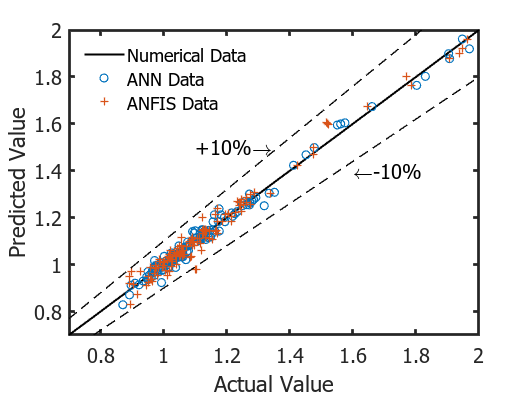

figure()
plot(0:5,0:5,'color','k','LineWidth',1.5); hold on;
xlim([0.7 2])
ylim([0.7 2])
plot(T(:,8),T(:,6),'o','color','#0072BD','LineWidth',0.9)
xlabel('Actual Value')
ylabel('Predicted Value')
% plot(T(:,12),T(:,6),'o','color','b');
plot(T(:,10),T(:,6),'+','color',"#D95319",'LineWidth',0.9);
x=0:5;
m1=(5.5/5);
y1=m1*x;
m2=(4.5/5);
y2=m2*x;
plot(x,y1,"LineStyle","--","Color","k",'LineWidth',1)
plot(x,y2,"LineStyle","--","Color","k",'LineWidth',1)
text(1.1,1.5,"+10%\rightarrow","FontSize",15,"FontName","Times")
text(1.6,1.4,"\leftarrow-10%","FontSize",15,"FontName","Times")
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2)
legend('Numerical Data','ANN Data','ANFIS Data','location','northwest',"Box","off");
% title('ΔP/ΔPo');
Sample_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/ΔP÷ΔPo_200sample.jpg');
exportgraphics(gcf,Sample_plot_name)
hold off

**Nusselt ratio comparison**

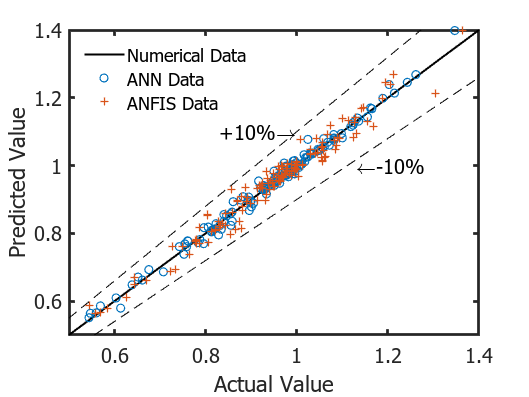

figure()
plot(0:5,0:5,'color','k','LineWidth',1.5); hold on;
xlim([0.5 1.4])
ylim([0.5 1.4])
plot(T(:,9),T(:,7),'o','color','#0072BD','LineWidth',0.9);
xlabel('Actual Value')
ylabel('Predicted Value')
% plot(T(:,13),T(:,7),'o','color','b');
plot(T(:,11),T(:,7),'+','color','#D95319','LineWidth',0.9);
plot(x,y1,"LineStyle","--","Color","k")
plot(x,y2,"LineStyle","--","Color","k")
text(0.83,1.1,"+10%\rightarrow","FontSize",15,"FontName","Times",'LineWidth',1)
text(1.13,1,"\leftarrow-10%","FontSize",15,"FontName","Times",'LineWidth',1)
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2)
legend('Numerical Data','ANN Data','ANFIS Data','location','northwest',"Box","off");
% title('ΔNu/ΔNuo');
Sample_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/ΔNu÷ΔNuo_200sample.jpg');
exportgraphics(gcf,Sample_plot_name)
hold off

## RELATIVE ERROR

**Nusselt ratio**

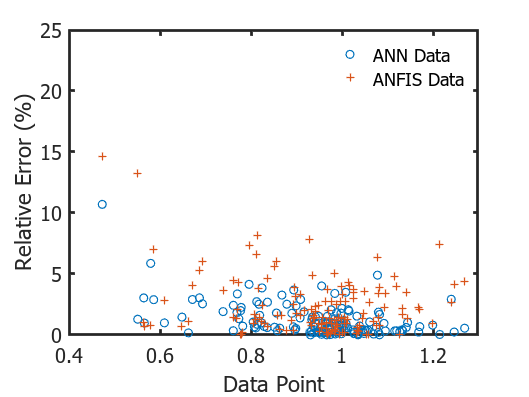

R_er_p_ann=Relativeerror(T(:,7),T(:,9));
R_er_p_anfis=Relativeerror(T(:,7),T(:,11));
% R_er_p_dt=R_error(T(:,7),T(:,13));
plot(T(:,7),R_er_p_ann,"o",'color','#0072BD','LineWidth',0.9); hold on
plot(T(:,7),R_er_p_anfis,'+','color','#D95319','LineWidth',0.9)
% plot(T(:,6),R_er_p_dt,'o','color','b')
xlim([0.4 1.3])
ylim([0 25])
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2)
xlabel('Data Point')
ylabel('Relative Error (%)')
legend('ANN Data','ANFIS Data','location','northeast',"Box","off")
Relative_err_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/Relative error Nu 200sample.jpg');
exportgraphics(gcf,Relative_err_plot_name)
hold off

**Pressure Ratio**

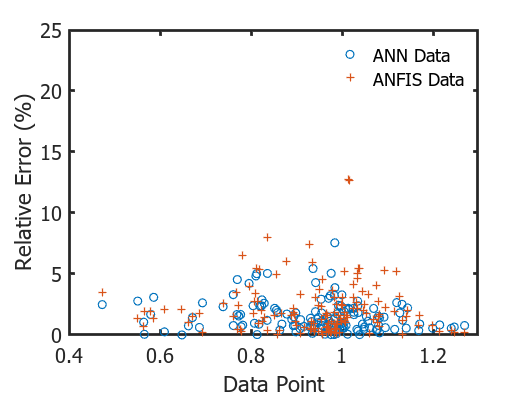

figure()
R_er_p_ann=Relativeerror(T(:,6),T(:,8));
R_er_p_anfis=Relativeerror(T(:,6),T(:,10));
% R_er_p_dt=R_error(T(:,7),T(:,13));
plot(T(:,7),R_er_p_ann,"o",'color','#0072BD','LineWidth',0.9); hold on
plot(T(:,7),R_er_p_anfis,'+','color','#D95319','LineWidth',0.9)
% plot(T(:,6),R_er_p_dt,'o','color','b')
xlim([0.4 1.3])
ylim([0 25])
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times','LineWidth',2)
xlabel('Data Point')
ylabel('Relative Error (%)')
legend('ANN Data','ANFIS Data','location','northeast',"Box","off")
Relative_err_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/Relative error P 200sample.jpg');
exportgraphics(gcf,Relative_err_plot_name)
hold off

figure('Position',[0 0 1150 800])
T_nu_disp_bar=T_nu(2:6,:)

T_nu_disp_bar = 5×5 table
      mae          mse         rmse        Rsq       mape 
    ________    _________    ________    _______    ______

     0.03911    0.0033294    0.057701    0.87144    4.6672
     0.02422    0.0013551    0.036811    0.94768     2.976
    0.022993    0.0010779    0.032831    0.95838    2.7067
    0.023466    0.0013117    0.036218    0.94935     2.881
    0.028279    0.0015975    0.039969    0.93831    3.3756


T_p_disp_bar=T_p(2:6,:)

T_p_disp_bar = 5×5 table
      mae          mse         rmse        Rsq       mape 
    ________    _________    ________    _______    ______

    0.032559    0.0024409    0.049405    0.98099    2.6555
     0.02363    0.0011167    0.033417     0.9913    1.9735
    0.022822    0.0010671    0.032667    0.99169    1.9548
    0.023304    0.0010536    0.032459     0.9918    1.9809
    0.032447     0.002446    0.049457    0.98095    2.6514


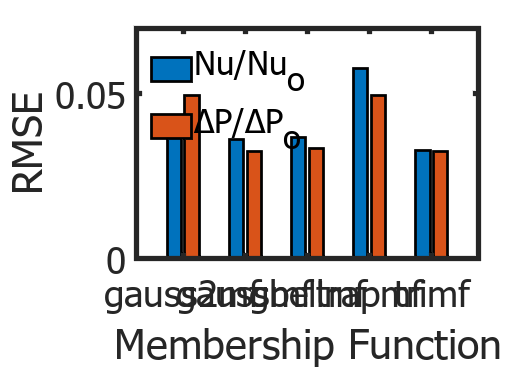

T_bar_anfis=array2table(cat(2,table2array(T_nu_disp_bar),table2array(T_p_disp_bar)));
bar(categorical(T_nu_disp{1:5,1}),T_bar_anfis{1:5,{'Var3','Var8'}},'EdgeColor',"k","LineWidth",2)
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',28,...
'FontName','Times','LineWidth',4)
xlabel('Membership Function')
ylabel('RMSE')
xtickangle(0)
ylim([0 0.07])
legend("Nu/Nu_o","ΔP/ΔP_o",'location','northwest',"Box","off");
name_bar_anfis=sprintf("D:/Matlab Drive/Research/Fuzzy/Figure/RMSE anfis.jpg");
exportgraphics(gcf,name_bar_anfis)

% hold on
% figure()
% T_nu_disp_bar=T_nu(2:6,:)
% T_p_disp_bar=T_p(2:6,:)
% T_bar_anfis=array2table(cat(2,table2array(T_nu_disp_bar),table2array(T_p_disp_bar)));
% yline(1,'--')
% bar(categorical(T_nu_disp{1:5,1}),T_bar_anfis{1:5,{'Var4','Var9'}})
% set(gca,...
% 'Units','normalized',...
% 'FontUnits','points',...
% 'FontWeight','normal',...
% 'FontSize',15,...
% 'FontName','Times')
% xlabel('Membership Function')
% ylabel('R^2 score')
% ylim([0 1.4])
% legend("Nu/Nu_o","ΔP/ΔP_o",'location','northwest',"Box","off");
% name_bar_anfis=sprintf("D:/Matlab Drive/Research/Fuzzy/Figure/R2 score.jpg");
% exportgraphics(gcf,name_bar_anfis)
% hold off

figure('Position',[0 0 1150 800])
min(rms_val_lm);
min(rms_val_scg);
min(rms_val_bay);
name_min_error={'Levenberg','Bayesian',"SCG"};
T_min_error_=array2table(cat(1,min(rms_val_lm),min(rms_val_bay),min(rms_val_scg)),"VariableNames",{'Pressure Drop Ratio','Nusselt Number Ratio'});
T_min_error=cat(2,name_min_error',T_min_error_)

T_min_error = 3×3 table
       Var1        Pressure Drop Ratio    Nusselt Number Ratio
    ___________    ___________________    ____________________

    "Levenberg"         0.022074                0.017847      
    "Bayesian"          0.020295                 0.01796      
    "SCG"               0.036575                0.030021      


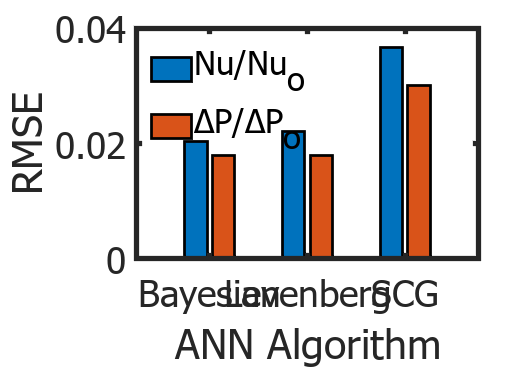

bar(categorical(T_min_error{:,1}),T_min_error{:,{'Pressure Drop Ratio','Nusselt Number Ratio'}},'EdgeColor',"k","LineWidth",2)
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',28,...
'FontName','Times','LineWidth',4)
xlabel('ANN Algorithm')
ylabel('RMSE')
xtickangle(0)
legend("Nu/Nu_o","ΔP/ΔP_o","Location","northwest","Box","off");
name_bar_ann=sprintf("D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison (new)/RMSE.jpg");
exportgraphics(gcf,name_bar_ann)